clf
clear all

format shortg




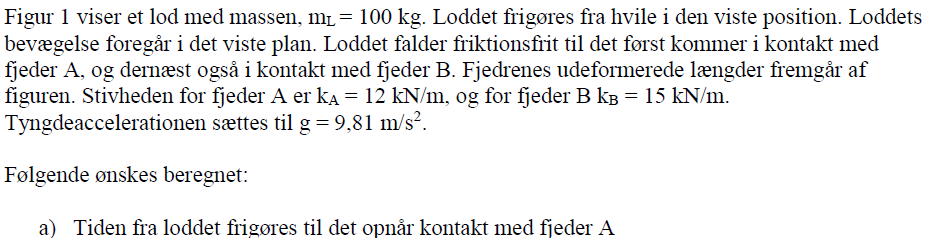

m_L = 100;
k_A = 12000; %N/m
k_B = 15000; %N/m

g = 9.81;


Loddet frigøres med hastigheden $v_0 = 0$ således får vi

y = 0.75; %m
syms t
eq = y == g * t^2 /2

$$eq = \frac{3}{4}=\frac{981\,t^{2}}{200}$$


t_sol = solve(eq, t);
t_A = t_sol(2);
vpa(t_A, 4)

$$ans = 0.391$$

Tiden til loddet rammer fjeder A er således $0,391\ s$

b)Loddets hastighed ved kontakt med fjeder A

v = g * t_A;
vpa(v)

$$ans = 3.8360135557633265485707248211545$$

Hastigheden er ved kontakt med fjederen $3,84\ m/s$

c) Loddets kinetiske energi, når loddet opnår kontakt med fjeder A

T = 1/2 * m_L * v^2;
vpa(T)

$$ans = 735.75$$

Den kinetiske energi af lodet ved A er $735,75\ J$

d) Loddets bevægelsesmængde (linear momentum) når loddet opnår kontakt med fjeder A

G = v * m_L;
vpa(G)

$$ans = 383.60135557633265485707248211545$$

Loddets bevægelsesmængde er således $383,6\ kg * m / s$

e) Den maksimale sammentrykning af fjeder A, når loddet igen kommer i hvile

Impulsbevarelse:

% x = 0.1
syms x
G_lod = m_L * g * (x + 0.75)

$$G\_lod = 981\,x+\frac{2943}{4}$$

K_A = k_A * (x)^2 / 2 

$$K\_A = 6000\,x^{2}$$

K_B = k_B * (x-0.1)^2 / 2  

$$K\_B = 7500\,{\left(x-\frac{1}{10}\right)}^{2}$$


eq = G_lod == K_A + K_B % her kan ikke bruges kinetisk energi da vi ikke kender hastigheden efter A

$$eq = 981\,x+\frac{2943}{4}=7500\,{\left(x-\frac{1}{10}\right)}^{2}+6000\,x^{2}$$


x_tryk = solve(eq, x)

$$x\_tryk = \left(\begin{array}{c} \frac{827}{9000}-\frac{\sqrt{4648429}}{9000}\\ \frac{\sqrt{4648429}}{9000}+\frac{827}{9000} \end{array}\right)$$

vpa(x_tryk(2),4)

$$ans = 0.3314$$

% G = -F * 


Således trykkes fjederene 0,33 m ned fra A